# Load parameters

allParameters = readmatrix(uigetfile('*.xlsx'));

[filename, filepath] = uigetfile('*.csv');
maxStress=zeros(12,1)

maxStress =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


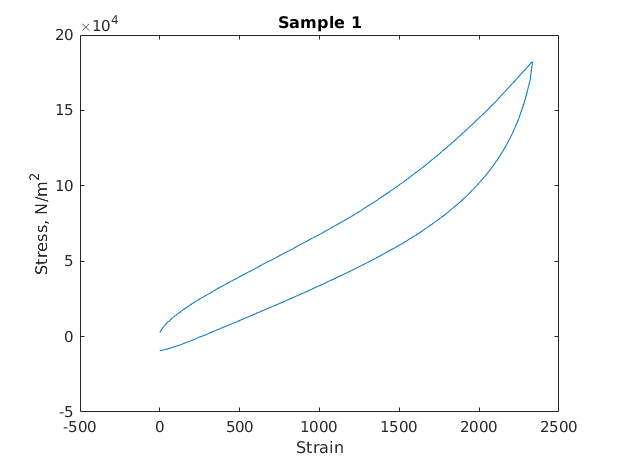

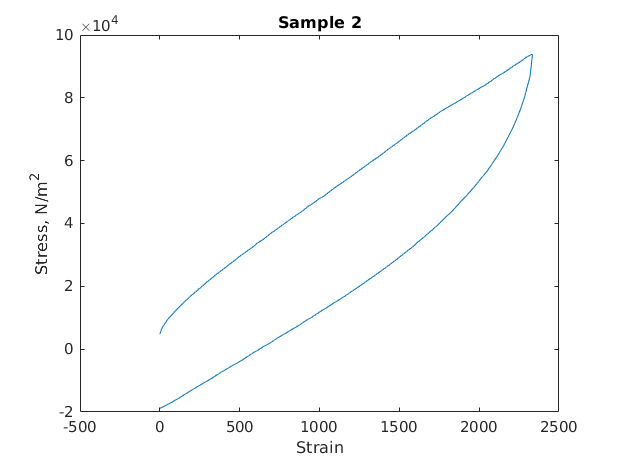

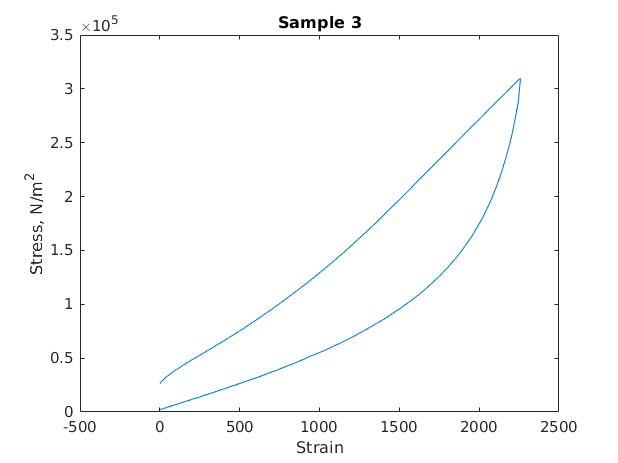

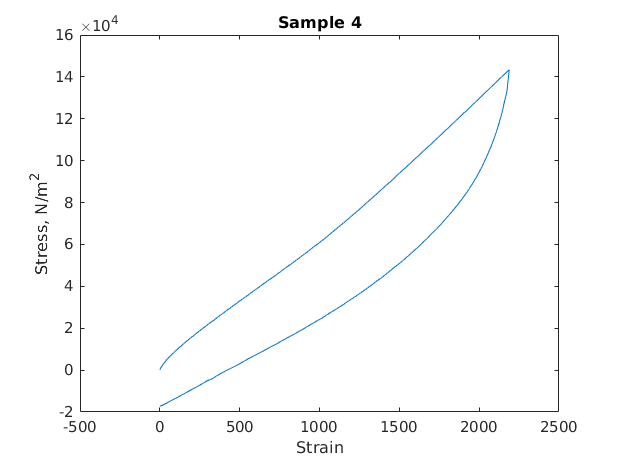

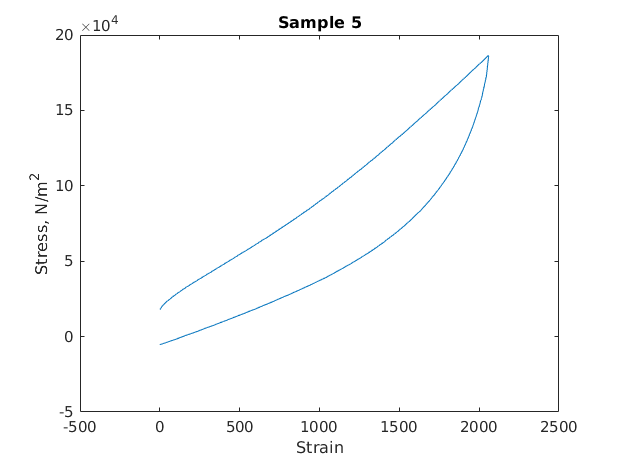

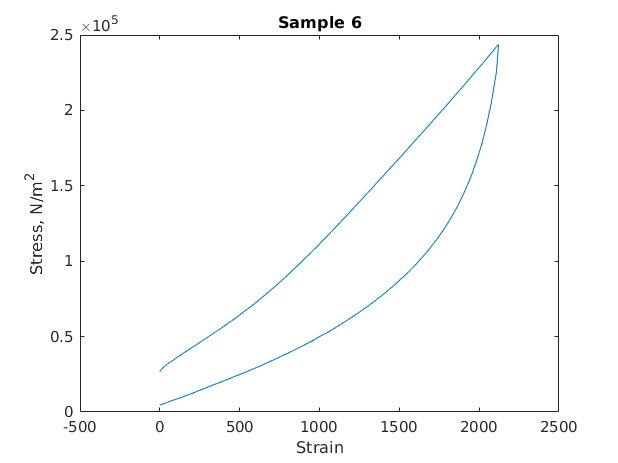

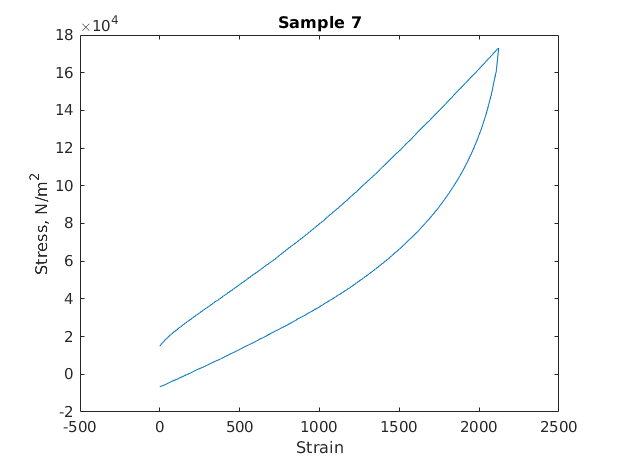

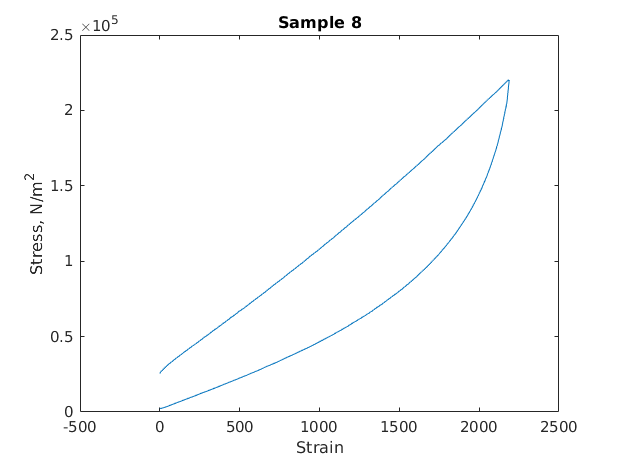

for i = 1:12
    [time,displacement,force]=importData(i, filename, filepath);
    [strain, stress] = generatePlots(i, allParameters, displacement, force);
    figure,plot(strain,stress);
    xlabel('Strain'); ylabel('Stress, N/m^2')
    plotTitle=['Sample ' num2str(i)]; title(plotTitle);
end

median(maxStress)

ans = 0

function [time, displacement,force] = importData(i, filename, filepath)
    %Match pattern to dynamically read the files
    filename = regexprep(filename, '_\d+\d?+_', ['_',num2str(i),'_']);
    T = readmatrix([filepath filename]);
    time = T(:,1);
    displacement = T(:,2);
    force=T(:,3);
end
function [strain, stress] = generatePlots(i, allParameters,displacement, force)
        % set parameters for the particular graph we're working on.
        parameters=allParameters(allParameters(:,3)==i,:);
        %Take dimensions from our set of parameters
        A=parameters(6)*parameters(8)*1e-6; %Width * length in m^2
        L = parameters(8)*1e-3;
        stress=force/A;
        strain=displacement/L;
end